# **WSN simulation and Calculating Network's Lifetime **

### **This project focuses on modeling and simulating a Wireless Sensor Network (WSN) to analyze its performance in terms of network lifetime under different configurations. A homogeneous WSN with energy-constrained nodes is deployed in a fixed area , but distributed in a random fashion , and both direct and dual-hop transmission schemes are studied. The primary goal is to optimize the network's lifetime by varying parameters such as transmission radius and sink location, using a simplistic energy consumption model.**

### **- In this project, we will analyze and demonstrate the following:**

            1.Generate a WSN with 100 sensor nodes in a 100*100 m^(2) area with the sink at the center of the network . 

            2. Use direct transimission for sensor nodes within R=30 , and dual hop transimission for others with distance greater than R =30 . 

            3.Plot number of active nodes versus number of cycles ,  determining Network Life time at T1 , and the remaining energy after T1 . 

            4.See the same impact when the transimission radious is taken a rangeو  and find the transimission radious that maximize Network life time . 

            5. Change the position of Sink and repeat Parts again , to see how would the network work if the sink where too much far away from the snesors  . 

            6. Finding out a new criteria for selecting relay node . 

-  **Clearing the working space, Close whole figures, before starting :  **

close all;
clear all;
clc;

- **Defining the Parameters that will be used across the scope of the project :**

% Parameters
N = 100;                                                    % Number of sensor nodes
A = 100;                                                    % Network area size (100m x 100m)
x = randi([0, A], 1, N);                                    % X-coordinates of sensor nodes
y = randi([0, A], 1, N);                                    % Y-coordinates of sensor nodes
E_initial = 2;                                              % Initial energy for each node (2 Joules)
sink = [A/2, A/2];                                          % Sink located at the center
Eelec = 50e-9;                                              % Energy for running transmitter/receiver circuitry (J/bit)
Eagg= 50e-9;                                                % Energy for aggretation 
epsilon_fs = 10e-9;                                         % Free-space energy parameter (J/bit/m^2)
epsilon_mp = 0.0013e-9;                                     % Multi-path energy parameter (J/bit/m^4)
d0 = sqrt(epsilon_fs / epsilon_mp);                         % Threshold distance
k = 4000;                                                   % Number of bits transmitted per cycle
R = 30;                                                     % Transmission range for direct communication


% Initialzie nodes energy and poistions 
E = E_initial * ones(1, N);                                 % Initialize energy for all nodes for R=30 
sensor_energy = E_initial * ones(1, N);                     % Initialize energy for all nodes for R that take a range 
sensor_energy_Optimal_Radious = E_initial * ones(1, N);     % Initialize energy for all nodes for optimal transimission radious
remaining_energy = zeros(N, 1);                             % Track remaining energy at each cycle for R=30 
remaining_energy_per_node_Optimal_Radious = zeros(N, 1);    % Track remaining energy at each cycle  for optimal transimission radious
node_dead = false(1, N);                                    % Track dead nodes at R=30 
node_status_dead = false(1, N);                             % Track dead nodes at R that takes a range 
node_status_dead_Optimal_Radious = false(1, N);             % Track dead nodes at R that takes an optimal radious 
alive_nodes = N;                                            % Number of alive nodes for R=30 
active_node_count = N;                                      % Number of active nodes for R that takes a range  
alive_nodes_Optimal_Radious = N;                            % Number of alive  nodes for R equalivent for optimal transimission radious 
alive_nodes_per_cycle = [];                                 % store number of active nodes per cycle for R=30 
active_nodes_per_cycle = [];                                % store number of active nodes per cycle for R that takes a range 
alive_nodes_per_cycle_Optimal_Radious = [];                 % store number of active nodes per cycle for R at optiaml transimission Radious 
remaining_energy_per_cycle = [];                            % Track remaining energy per cycle for R=30 
remaining_energy_per_cycle_Optimal_Radious = [];            % Track remaining energy per cycle for R at optimal transimission radious 
cycles = 0;                                                 % Cycle count for R=30 
simulation_cycles = 0;                                      % Cycle count for R that takes a Range 
simulation_cycles_Optimal_Radious = 0;                      % Cycle count for R that takes the optimal transimission radious 

% Preallocate arrays for dead node indices due to sink in the Center 
dead_nodes_T1 = [];                                         % Allocate the indicies of dead nodes through the first Cycle
dead_nodes_at_T1 = [];                                      % Store dead nodes at T1
dead_nodes_at_T1_Optimal_Radious = [];                      % Track dead nodes at T1

  **Part A **** The network topology with 100 sensors randomly deployed , with the sink at the center :**

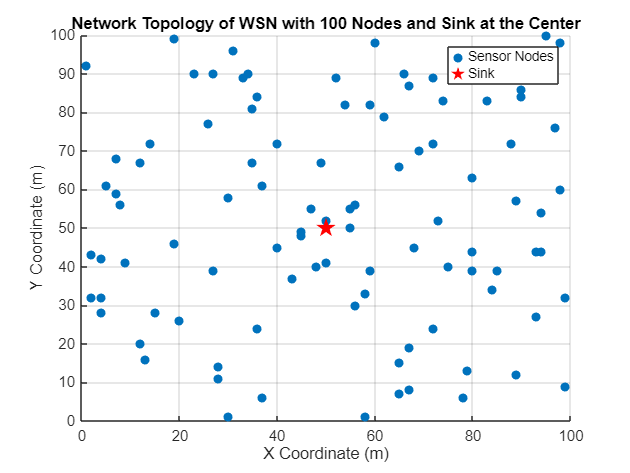

figure(1);
scatter(x, y, 'filled');                                                % Plot sensor nodes
hold on;
plot(sink(1), sink(2), 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); % Plot sink
title('Network Topology of WSN with 100 Nodes and Sink at the Center');
xlabel('X Coordinate (m)');
ylabel('Y Coordinate (m)');
legend('Sensor Nodes', 'Sink');
grid on;

                                                               **   Figure [1] **

**                    The figure show the network with 100 sensors randomly deployed , **

**                             and the sink at the center of the network at (50,50) .**

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

- **The simulation models sensor nodes transmitting data based on their distance from the sink node. If the distance between a sensor and the sink is less than a defined threshold transimission radious *****R*****, the sensor uses a direct transmission model, which consumes less energy. For sensors located farther than *****R*****, a dual-hop transmission model is applied, where the data is relayed through an intermediate sensor node to the sink, consuming less energy in comprasion with direct transimission . A sensor node depletes its energy and dies when its remaining energy is insufficient to continue transmission, simulating the gradual exhaustion of its energy resources over time.**

- **The relay function is designed to identify the most suitable relay node for transmission, such that the total distance from the source node to the relay node and from the relay node to the sink is minimized.**

function best_relay = find_best_relay(src_idx, sink, x, y, node_dead)
    % Function to find the best relay node
    % Inputs:
    % - src_idx: Index of the source node
    % - sink: Coordinates of the sink [x_sink, y_sink]
    % - x, y: Coordinates of all nodes
    % - node_dead: Boolean array indicating if a node is dead
    %
    % Output:
    % - best_relay: Index of the best relay node
    N = length(x);                         % Total number of nodes
    min_distance_sum = Inf;                % Initialize to infinity
    best_relay = -1;                       % Default value if no relay is found
    for i = 1:N
        if ~node_dead(i) && i ~= src_idx   % Exclude dead nodes and the source node
            distance_to_relay = sqrt((x(src_idx) - x(i))^2 + (y(src_idx) - y(i))^2);
            distance_relay_to_sink = sqrt((x(i) - sink(1))^2 + (y(i) - sink(2))^2);
            total_distance = distance_to_relay + distance_relay_to_sink;
            if total_distance < min_distance_sum
                min_distance_sum = total_distance;
                best_relay = i;
            end
        end
    end
    if best_relay == -1
        error('No suitable relay node found.');
    end
end

% Simulation loop
while alive_nodes > 0

indecies of Dead nodes at T1: 98


    remaining_energy = E;                         % Record energy before updating for the current cycle

     1



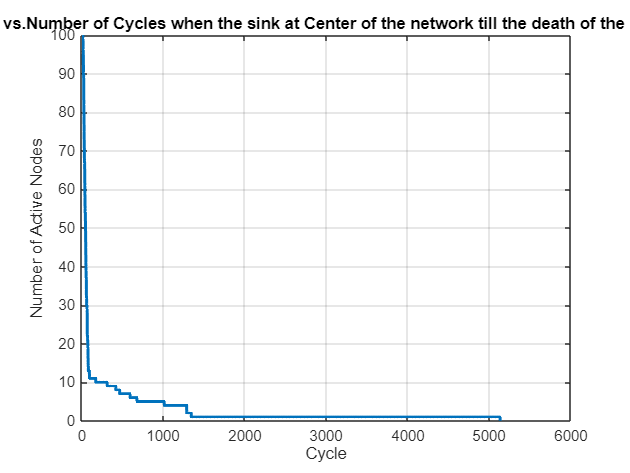

    for i = 1:N
        if ~node_dead(i) && E(i) > 0              % Process only active nodes
            distance_to_sink = sqrt((x(i) - sink(1))^2 + (y(i) - sink(2))^2);
            if distance_to_sink <= R
                 % Source node energy consumption (only for sending its own data)
                if distance_to_sink <= d0
                    energy_consumed = k * Eelec + k * epsilon_fs * distance_to_sink^2;
                else
                    energy_consumed = k * Eelec + k * epsilon_mp * distance_to_sink^4;
                end

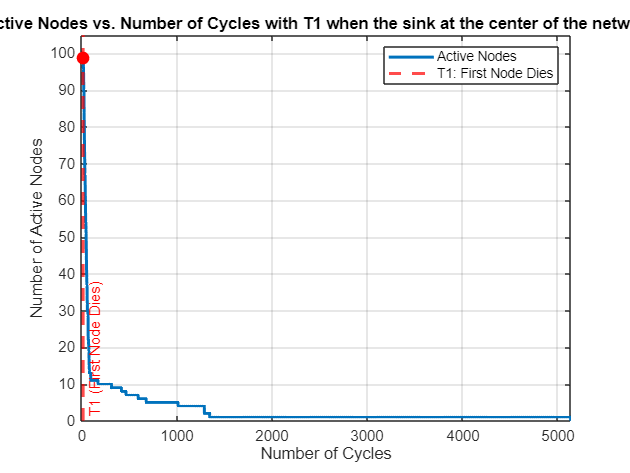

               
           else
                % Dual-hop transmission
                best_relay = find_best_relay(i, sink, x, y, node_dead);
                distance_to_relay = sqrt((x(i) - x(best_relay))^2 + (y(i) - y(best_relay))^2);
                distance_relay_to_sink = sqrt((x(best_relay) - sink(1))^2 + (y(best_relay) - sink(2))^2);
                % Source node energy consumption (only for sending its own data)
                if distance_to_relay <= d0
                    energy_consumed = k * Eelec + k * epsilon_fs * distance_to_relay^2;
                else
                    energy_consumed = k * Eelec + k * epsilon_mp * distance_to_relay^4;
                end
                % Relay node energy consumption (receiving + forwarding + aggregating)
                % Aggregation energy is added here
                if distance_relay_to_sink <= d0
                    relay_energy_consumed = k * Eelec + k * epsilon_fs * distance_relay_to_sink^2 + k * Eagg;
                else
                    relay_energy_consumed = k * Eelec + k * epsilon_mp * distance_relay_to_sink^4 + k * Eagg;
                end

                % Deduct energy for the relay node
                if E(best_relay) > relay_energy_consumed
                    E(best_relay) = E(best_relay) - relay_energy_consumed;
                else
                    % Relay node death handling
                    node_dead(best_relay) = true;
                    alive_nodes = alive_nodes - 1;
                    if isempty(dead_nodes_T1) && alive_nodes == N-1

                        dead_nodes_T1 = find(node_dead); % Store dead nodes at T1
                    end
                end
            end

            % Deduct energy from the source node
            if E(i) > energy_consumed
                E(i) = E(i) - energy_consumed;
            else

T1 (First node dies): 13 cycles


                % Source node death handling
                node_dead(i) = true;
                alive_nodes = alive_nodes - 1;
                if isempty(dead_nodes_T1) && alive_nodes == N-1
                    dead_nodes_T1 = find(node_dead); % Store dead nodes at T1
                end
            end
        end 
    end 

    % Store alive nodes for this cycle
    alive_nodes_per_cycle = [alive_nodes_per_cycle, alive_nodes];
    remaining_energy_per_cycle = [remaining_energy_per_cycle; E]; % Store remaining energy after this cycle
    cycles = cycles + 1; % Increment cycle count
end

- **The indicies, count of First nodes death :**

disp(['indecies of Dead nodes at T1: ', num2str(dead_nodes_T1)]);
disp(length(dead_nodes_T1));

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part B**** Number of active nodes versus number of cycles , till the death of Last node at R=30  :  **

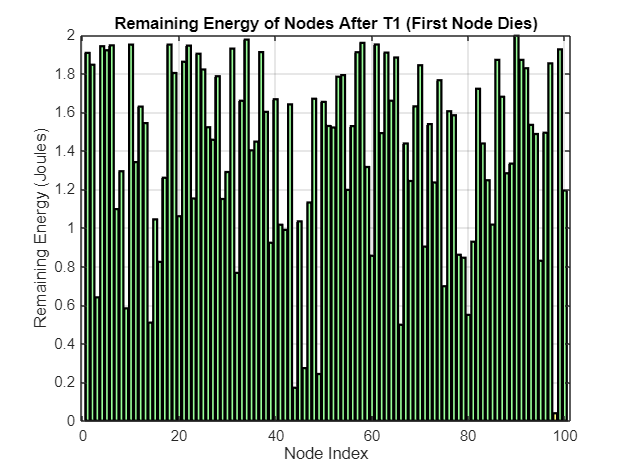

% plot for number of active nodes versus number of cycles 
figure(2);

plot(1:cycles, alive_nodes_per_cycle, 'LineWidth', 2);
title('Number of Active Nodes vs.Number of Cycles when the sink at Center of the network till the death of the last node for R = 30 meters ');
xlabel('Cycle');
ylabel('Number of Active Nodes');
grid on;

**                                                                Figure [2] **

**              The figure show number of active nodes (not dead ) ,  versus the number of cycles , **

**                        till the death of last node  , when the sink is at Center of the Network till the **

**                                                 death of the last node for R = 30 meters.**

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part C_1**** The network Life time , is indicated by T1, which indicates the Cycle at which First node dead : **

%  Mark T1 on the plot
T1 = find(alive_nodes_per_cycle == N-1, 1);       % First node dies

% Plot vertical lines to mark T1
hold on;
xline(T1, 'r--', 'LineWidth', 2, 'Label', 'T1 (First Node Dies)', 'LabelVerticalAlignment', 'bottom');

% Annotations for T1
plot(T1, alive_nodes_per_cycle(T1), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

% Adjust axis limits for wider scale
xlim([0 max(T1*1.2, length(alive_nodes_per_cycle))]); % Expands the x-axis by 20% more than T3
ylim([0 N+5]); % Adds a small buffer to the y-axis to give more space for labels

% Add labels and grid
title('Number of Active Nodes vs. Number of Cycles with T1 when the sink at the center of the network ,when R=30 ');
xlabel('Number of Cycles');
ylabel('Number of Active Nodes');
grid on;
legend('Active Nodes', 'T1: First Node Dies');
hold off;

**                                                               Figure [3] **

**             The figure show number of active nodes (not dead ) , versus the number of **

**                cycles , till the death of last node , and indiction for T1 , when the sink **

**                                         is at the center , and R =30 . **

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part C_2**** The Cycles at which First Node : **

% Display the T1
disp(['T1 (First node dies): ', num2str(T1), ' cycles']);

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part C_3**** The remaining energy at the network for sensor nodes , after T1  LifeTime : **

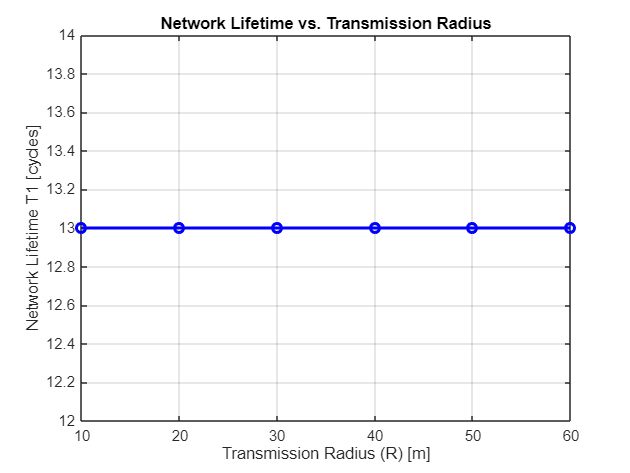

figure(4);
% Create a bar plot for the remaining energy at T1
bar_handles = bar(remaining_energy_per_cycle(T1, :)); 
title('Remaining Energy of Nodes After T1 (First Node Dies)');
xlabel('Node Index');

ylabel('Remaining Energy (Joules)');
grid on;

% Set the colormap for alive (faded green) and dead (vibrant orange) nodes
faded_alive_color = [0.6, 1, 0.6]; % Light pastel green for alive nodes
bright_dead_color = [1, 1, 0.5];   % Vibrant orange for dead nodes

% Highlight nodes by changing their colors
hold on;
for i = 1:length(bar_handles.YData)

Optimal Transmission Radius R: 10 meters, Network Lifetime T1: 13 cycles.


    if ismember(i, dead_nodes_T1)
        % Set color for dead nodes (vibrant orange)
        bar(i, remaining_energy_per_cycle(T1, i), 'FaceColor', bright_dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        % Set color for alive nodes (faded green)
        bar(i, remaining_energy_per_cycle(T1, i), 'FaceColor', faded_alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off;

**                                                                Figure [4]**

**                    The figure shows the remaining energy at the network , after T1 life time ,**

**                            in which the green items indicates the remaining energy for alive nodes **

**                               , and the yellow items indicates the remaining energy for dead nodes. **

- **Observation :**** After T1 life time there's just one node dead and the other nodes are alive , and the range of energies for whole sensor nodes is among [0,2] , in which 0 indicates the sensor nodes , which have lost their energies , while 2 indicates the sensors that haven't lose any energies , and node is  considered as dead node when the remaining energy is less than the requried energy for transimission   . **

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

- **Defining a transimission radious that takes a range from [10 : 10 : max (R) ] , in which R is the distance that directly transimit to the sink , and simulate the model for each value of the transimission radious , to find the value of transimission radious that maximize the network life time at T1, and plot the remaining energy after T1 cycle in case of optimal transimission radious  . **

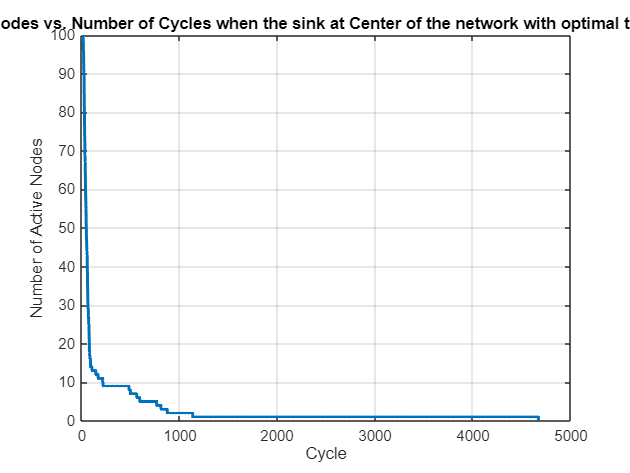

distances_to_sink_1 = sqrt((x - sink(1)).^2 + (y - sink(2)).^2);
max_R = max(distances_to_sink_1);                                       % Maximum distance for direct communication
% Define range of transmission radii
R_values = 10:10:ceil(max_R);                                           % Range of transmission radii (from 10m to 100m)
T1_values = zeros(1, length(R_values));                                 % Array to store T1 for each R
% Loop over different values of transmission radius

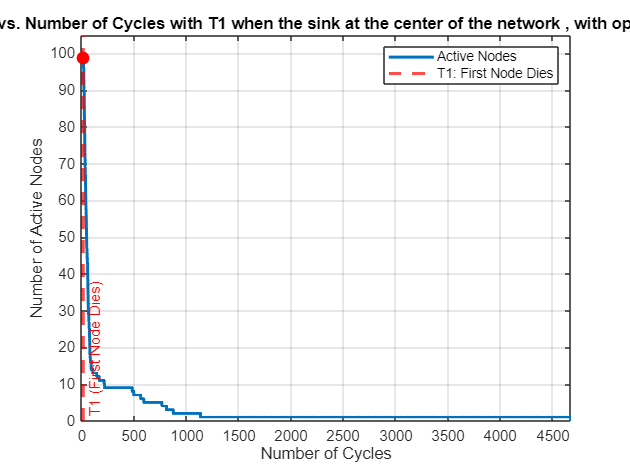

for radius_idx = 1:length(R_values)
    transmission_radius = R_values(radius_idx);                           % Current transmission radius

    % Simulation loop
    while active_node_count > 0
        for node_idx = 1:N
            if ~node_status_dead(node_idx) && sensor_energy(node_idx) > 0 % Only process active nodes
                distance_to_sink = sqrt((x(node_idx) - sink(1))^2 + (y(node_idx) - sink(2))^2);
                if distance_to_sink <= transmission_radius
                     if distance_to_sink <= d0
                         energy_consumed = k * Eelec + k * epsilon_fs * distance_to_sink^2;
                    else
                         energy_consumed = k * Eelec + k * epsilon_mp * distance_to_sink^4;
                     end                   
                else
                    % Dual-hop transmission
                    best_relay_node = find_best_relay(node_idx, sink, x, y, node_status_dead);
                    distance_to_relay = sqrt((x(node_idx) - x(best_relay_node))^2 + (y(node_idx) - y(best_relay_node))^2);
                    distance_relay_to_sink = sqrt((x(best_relay_node) - sink(1))^2 + (y(best_relay_node) - sink(2))^2);
                    % Source node energy consumption
                    if distance_to_relay <= d0
                        energy_consumed = k * Eelec + k * epsilon_fs * distance_to_relay^2;

                    else
                        energy_consumed = k * Eelec + k * epsilon_mp * distance_to_relay^4;
                    end
                    
                    % Relay node energy consumption
                    if distance_relay_to_sink <= d0
                        relay_energy_consumed = k * Eelec + k * epsilon_fs * distance_relay_to_sink^2 + k * Eagg;

T1 (First node dies): 13 cycles


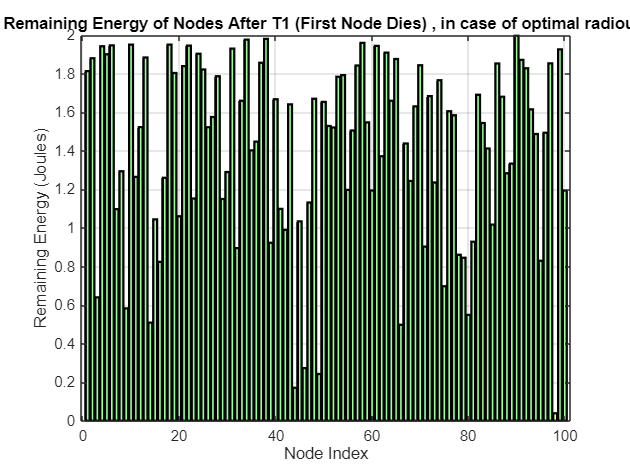

                    else
                        relay_energy_consumed = k * Eelec + k * epsilon_mp * distance_relay_to_sink^4 + k * Eagg;
                    end
                    
                    if sensor_energy(best_relay_node) > relay_energy_consumed
                        sensor_energy(best_relay_node) = sensor_energy(best_relay_node) - relay_energy_consumed;
                    else
                        node_status_dead(best_relay_node) = true;
                        active_node_count = active_node_count - 1;
                        if isempty(dead_nodes_at_T1) && active_node_count == N - 1
                            dead_nodes_at_T1 = find(node_status_dead);
                        end
                    end
                end

                if sensor_energy(node_idx) > energy_consumed
                    sensor_energy(node_idx) = sensor_energy(node_idx) - energy_consumed;
                else
                    node_status_dead(node_idx) = true;
                    active_node_count = active_node_count - 1;
                    if isempty(dead_nodes_at_T1) && active_node_count == N - 1
                        dead_nodes_at_T1 = find(node_status_dead);

                    end
                end
            end
        end

        % Store active nodes per cycle
        active_nodes_per_cycle = [active_nodes_per_cycle, active_node_count];
        simulation_cycles = simulation_cycles + 1;
    end
    % Store network lifetime for current transmission radius
    T1_values(radius_idx) = find(active_nodes_per_cycle == N - 1, 1);
end

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part D_1 ****The Network lifetime T1 versus the Transimission radious R :**

figure(5);
plot(R_values, T1_values, 'b-o', 'LineWidth', 2);
xlabel('Transmission Radius (R) [m]');
ylabel('Network Lifetime T1 [cycles]');
title('Network Lifetime vs. Transmission Radius');
grid on;

                                                                   ** Figure [5]**

**                      The figure shows the Network Life Time at each one of  the transimission **

**                                      radious , till the maximum transimission radious**

**                                                           for direct transimission . **

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part D_2****  The optimum Transimission radious that maximize T1 : **

[~, optimal_transmission_radius_idx] = max(T1_values);
optimal_transmission_radius = R_values(optimal_transmission_radius_idx);
disp(['Optimal Transmission Radius R: ', num2str(optimal_transmission_radius), ' meters, Network Lifetime T1: ', num2str(T1_values(optimal_transmission_radius_idx)), ' cycles.']);

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

- **Simulating the model with the optimal transmission radius to generate various plots: one showing the number of active nodes versus the number of cycles, highlighting the value of T1, and another indicating the remaining network energy at T1 under the optimal transmission radius.**

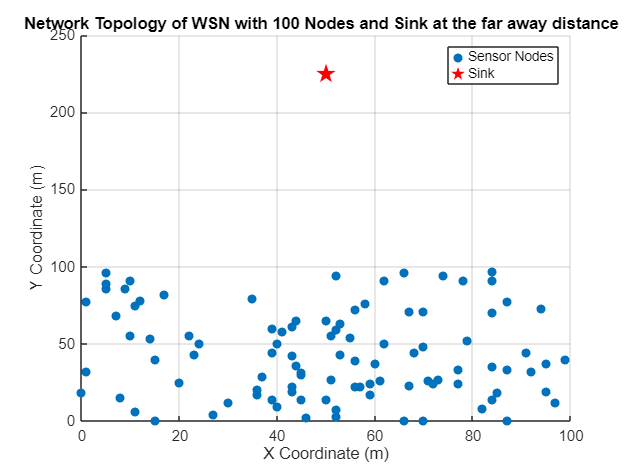

while alive_nodes_Optimal_Radious > 0
    for i = 1:N
        if ~node_status_dead_Optimal_Radious(i) && sensor_energy_Optimal_Radious(i) > 0
            distance_to_sink = sqrt((x(i) - sink(1))^2 + (y(i) - sink(2))^2);
            if distance_to_sink <= optimal_transmission_radius
                if distance_to_sink <= d0
                         energy_consumed = k * Eelec + k * epsilon_fs * distance_to_sink^2;
                else
                         energy_consumed = k * Eelec + k * epsilon_mp * distance_to_sink^4;
                end 
               
            else
                % Dual-Hop Transmission
                best_relay = find_best_relay(i, sink, x, y, node_status_dead_Optimal_Radious);
                distance_to_relay = sqrt((x(i) - x(best_relay))^2 + (y(i) - y(best_relay))^2);
                distance_relay_to_sink = sqrt((x(best_relay) - sink(1))^2 + (y(best_relay) - sink(2))^2);

                % Source Node Energy Consumption
                if distance_to_relay <= d0
                    energy_consumed = k * Eelec + k * epsilon_fs * distance_to_relay^2;
                else
                    energy_consumed = k * Eelec + k * epsilon_mp * distance_to_relay^4;
                end

                % Relay Node Energy Consumption
                if distance_relay_to_sink <= d0
                    relay_energy_consumed = k * Eelec + k * epsilon_fs * distance_relay_to_sink^2 + k * Eagg;
                else
                    relay_energy_consumed = k * Eelec + k * epsilon_mp * distance_relay_to_sink^4 + k * Eagg;
                end

                % Update Relay Node Energy
                if sensor_energy_Optimal_Radious(best_relay) > relay_energy_consumed
                    sensor_energy_Optimal_Radious(best_relay) = sensor_energy_Optimal_Radious(best_relay) - relay_energy_consumed;
                else
                    node_status_dead_Optimal_Radious(best_relay) = true;
                    alive_nodes_Optimal_Radious = alive_nodes_Optimal_Radious - 1;
                    if isempty(dead_nodes_at_T1_Optimal_Radious) && alive_nodes_Optimal_Radious == N - 1
                        dead_nodes_at_T1_Optimal_Radious = find(node_status_dead_Optimal_Radious);
                    end
                end
            end

            % Update Source Node Energy
            if sensor_energy_Optimal_Radious(i) > energy_consumed
                sensor_energy_Optimal_Radious(i) = sensor_energy_Optimal_Radious(i) - energy_consumed;
            else
                node_status_dead_Optimal_Radious(i) = true;
                alive_nodes_Optimal_Radious = alive_nodes_Optimal_Radious - 1;

                if isempty(dead_nodes_at_T1_Optimal_Radious) && alive_nodes_Optimal_Radious == N - 1
                    dead_nodes_at_T1_Optimal_Radious = find(node_status_dead_Optimal_Radious);
                end
            end
        end
    end

    % Store Alive Nodes and Energy Per Cycle
    alive_nodes_per_cycle_Optimal_Radious = [alive_nodes_per_cycle_Optimal_Radious, alive_nodes_Optimal_Radious];
    remaining_energy_per_cycle_Optimal_Radious = [remaining_energy_per_cycle_Optimal_Radious; sensor_energy_Optimal_Radious];
    simulation_cycles_Optimal_Radious = simulation_cycles_Optimal_Radious + 1;
end

Error using Project_2_WSN_Model_Main>find_best_relay (line 79)
No suitable relay node found.

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

figure(6);
plot(1:simulation_cycles_Optimal_Radious,alive_nodes_per_cycle_Optimal_Radious , 'LineWidth', 2);
title('Number of Active Nodes vs. Number of Cycles when the sink at Center of the network with optimal transimission radious  ');
xlabel('Cycle');
ylabel('Number of Active Nodes');
grid on;

**                                                                   Figure [6]**

**                       The figure shows number of active nodes , versus number of cycles till the**

**                                 death of last  node , in case of optimal transimission radious .  **

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

%  Mark T1 on the plot
T1_Optimal_radious = find(alive_nodes_per_cycle_Optimal_Radious == N-1, 1); % First node dies
% Plot vertical lines to mark T1
hold on;
xline(T1_Optimal_radious, 'r--', 'LineWidth', 2, 'Label', 'T1 (First Node Dies)', 'LabelVerticalAlignment', 'bottom');
% Annotations for T1
plot(T1_Optimal_radious, alive_nodes_per_cycle_Optimal_Radious(T1_Optimal_radious), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
% Adjust axis limits for wider scale
xlim([0 max(T1_Optimal_radious*1.2, length(alive_nodes_per_cycle_Optimal_Radious))]); % Expands the x-axis by 20% more than T3
ylim([0 N+5]); % Adds a small buffer to the y-axis to give more space for labels
% Add labels and grid
title('Number of Active Nodes vs. Number of Cycles with T1 when the sink at the center of the network , with optimal transimission radious ');
xlabel('Number of Cycles');
ylabel('Number of Active Nodes');
grid on;
legend('Active Nodes', 'T1: First Node Dies');
hold off;

**                                                                        Figure [7]**

**                       The figure shows number of active nodes , versus number of cycles till the**

**                                 death of last  node , in case of optimal transimission radious , **

**                                                            with indication for T1 . **

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

- **The Network life time T1 ,indicating the cycle at which first node dead , in case of optimal radious : **

disp(['T1 (First node dies): ', num2str(T1_Optimal_radious), ' cycles']);

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part D_3**** The Remaining energy at the network , after T1 in case of optimal Radious :**

figure(7);
T1_index = find(alive_nodes_per_cycle_Optimal_Radious == N - 1, 1);
bar_handles = bar(remaining_energy_per_cycle_Optimal_Radious(T1_index, :));
title('Remaining Energy of Nodes After T1 (First Node Dies) , in case of optimal radious ');
xlabel('Node Index');
ylabel('Remaining Energy (Joules)');
grid on;

% Customizing Bar Colors
alive_color = [0.6, 1, 0.6]; 
dead_color = [1, 1, 0.5];
hold on;
for i = 1:N
    if ismember(i, dead_nodes_at_T1_Optimal_Radious)
        bar(i, remaining_energy_per_cycle_Optimal_Radious(T1_index, i), 'FaceColor', dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        bar(i, remaining_energy_per_cycle_Optimal_Radious(T1_index, i), 'FaceColor', alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off;

**                                                                  Figure [8]**

**                       The figure shows the remaining energy at the network after T1, **

**                                in case of optimal transimission radious , in which **

**                                    green items indicates the alive nodes ,and yellow**

**                                             items indicates the dead nodes **

- **Observation :**** After T1 life time there's just one node dead and the other nodes are alive , and the range of energies for whole sensor nodes is among [0,2] , in which 0 indicates the sensor nodes , which have lost their energies , while 2 indicates the sensors that haven't lose any energies , and node is  considered as dead node when the remaining energy is less than the requried energy for transimission , it appears that less nodes have lost their energies  wity large amount , in comparsion with the pervious part when R=30   . **

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part E ****Simulating the Same pervious model , when sink is too much far away from the network , and see its impact of positioning on the different outcomes and plots :**

close all;
clear all;
clc;

% Parameters
N = 100;                                             % Number of sensor nodes
A = 100;                                             % Network area size (100m x 100m)
x = randi([0, A], 1, N);                             % X-coordinates of sensor nodes
y = randi([0, A], 1, N);                             % Y-coordinates of sensor nodes
E_initial = 2;                                       % Initial energy for each node (2 Joules)
sink = [A/2, A/2+175];                               % Sink located at too much far distance from the network 
Eelec = 50e-9;                                       % Energy for running transmitter/receiver circuitry (J/bit)
Eagg= 50e-9;                                         % Energy for aggretation 
epsilon_fs = 10e-9;                                  % Free-space energy parameter (J/bit/m^2)
epsilon_mp = 0.0013e-9;                              % Multi-path energy parameter (J/bit/m^4)
d0 = sqrt(epsilon_fs / epsilon_mp);                  % Threshold distance
k = 4000;                                            % Number of bits transmitted per cycle
R = 30;                                              % Transmission range for direct communication
    



% Initialzie nodes energy and poistions
E = E_initial * ones(1, N);                                 % Initialize energy for all nodes for R=30 
sensor_energy = E_initial * ones(1, N);                     % Initialize energy for all nodes for R that take a range 
sensor_energy_Optimal_Radious = E_initial * ones(1, N);     % Initialize energy for all nodes for optimal transimission radious
remaining_energy = zeros(N, 1);                             % Track remaining energy at each cycle for R=30 
remaining_energy_per_node_Optimal_Radious = zeros(N, 1);    % Track remaining energy at each cycle  for optimal transimission radious
node_dead = false(1, N);                                    % Track dead nodes at R=30 
node_status_dead = false(1, N);                             % Track dead nodes at R that takes a range 
node_status_dead_Optimal_Radious = false(1, N);             % Track dead nodes at R that takes an optimal radious 
alive_nodes = N;                                            % Number of alive nodes for R=30 
active_node_count = N;                                      % Number of active nodes for R that takes a range  
alive_nodes_Optimal_Radious = N;                            % Number of alive  nodes for R equalivent for optimal transimission radious 
alive_nodes_per_cycle = [];                                 % store number of active nodes per cycle for R=30 
active_nodes_per_cycle = [];                                % store number of active nodes per cycle for R that takes a range 
alive_nodes_per_cycle_Optimal_Radious = [];                 % store number of active nodes per cycle for R at optiaml transimission Radious 
remaining_energy_per_cycle = [];                            % Track remaining energy per cycle for R=30 
remaining_energy_per_cycle_Optimal_Radious = [];            % Track remaining energy per cycle for R at optimal transimission radious 
cycles = 0;                                                 % Cycle count for R=30 
simulation_cycles = 0;                                      % Cycle count for R that takes a Range 
simulation_cycles_Optimal_Radious = 0;                      % Cycle count for R that takes the optimal transimission radious 

% Preallocate arrays for dead node indices due to sink in the Center 
dead_nodes_T1 = [];                                         % Allocate the indicies of dead nodes through the first Cycle
dead_nodes_at_T1 = [];                                      % Store dead nodes at T1
dead_nodes_at_T1_Optimal_Radious = [];                      % Track dead nodes at T1


**Part  E_ A **** The network topology with 100 sensors randomly deployed , with the sink at too much far distance  :**

% Part A || Plot network topology
figure(9);
scatter(x, y, 'filled');                                                % Plot sensor nodes
hold on;
plot(sink(1), sink(2), 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); % Plot sink
title('Network Topology of WSN with 100 Nodes and Sink at the far away distance  ');
xlabel('X Coordinate (m)');
ylabel('Y Coordinate (m)');
legend('Sensor Nodes', 'Sink');
grid on;

                                                                    **    Figure [9]**

**                   The figure show the network with 100 sensor randomly deployed,  and the sink at too**

**                                    much far away distance from the edges of the newtork** 

% Simulation loop
while alive_nodes > 0
    remaining_energy = E;                         % Record energy before updating for the current cycle
    for i = 1:N
        if ~node_dead(i) && E(i) > 0 % Process only active nodes
            distance_to_sink = sqrt((x(i) - sink(1))^2 + (y(i) - sink(2))^2);
            if distance_to_sink <= R
                % Direct transmission
                energy_consumed = k * Eelec + k * epsilon_fs * distance_to_sink^2;
           else
                % Dual-hop transmission
                best_relay = find_best_relay(i, sink, x, y, node_dead);
                distance_to_relay = sqrt((x(i) - x(best_relay))^2 + (y(i) - y(best_relay))^2);
                distance_relay_to_sink = sqrt((x(best_relay) - sink(1))^2 + (y(best_relay) - sink(2))^2);

                % Source node energy consumption (only for sending its own data)
                if distance_to_relay <= d0
                    energy_consumed = k * Eelec + k * epsilon_fs * distance_to_relay^2;
                else                  
                    energy_consumed = k * Eelec + k * epsilon_mp * distance_to_relay^4;
                end

                % Relay node energy consumption (receiving + forwarding + aggregating)
                % Aggregation energy is added here
                if distance_relay_to_sink <= d0
                    relay_energy_consumed = k * Eelec + k * epsilon_fs * distance_relay_to_sink^2 + k * Eagg;
                else
                    relay_energy_consumed = k * Eelec + k * epsilon_mp * distance_relay_to_sink^4 + k * Eagg;
                end

                % Deduct energy for the relay node
                if E(best_relay) > relay_energy_consumed
                    E(best_relay) = E(best_relay) - relay_energy_consumed;
                else
                    % Relay node death handling
                    node_dead(best_relay) = true;
                    alive_nodes = alive_nodes - 1;
                    if isempty(dead_nodes_T1) && alive_nodes == N-1
                        dead_nodes_T1 = find(node_dead); % Store dead nodes at T1
                    end
                end
            end

            % Deduct energy from the source node
            if E(i) > energy_consumed
                E(i) = E(i) - energy_consumed;
            else
                % Source node death handling
                node_dead(i) = true;
                alive_nodes = alive_nodes - 1;
                if isempty(dead_nodes_T1) && alive_nodes == N-1
                    dead_nodes_T1 = find(node_dead); % Store dead nodes at T1
                end
            end
        end 
    end 

    % Store alive nodes for this cycle
    alive_nodes_per_cycle = [alive_nodes_per_cycle, alive_nodes];
    remaining_energy_per_cycle = [remaining_energy_per_cycle; E]; % Store remaining energy after this cycle
    cycles = cycles + 1; % Increment cycle count
end

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part E_B_0 ****The indicies , count fo First nodes death : **

disp(['indecies of Dead nodes at T1: ', num2str(dead_nodes_T1)]);
disp(length(dead_nodes_T1));

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part E_B_1**** Plot for number of active nodes versus number of cycles in case of sink at far away distnace and with R=30 : **

% Plot: Number of active nodes vs. cycles
figure(2);
plot(1:cycles, alive_nodes_per_cycle, 'LineWidth', 2);
title('Number of Active Nodes vs. Number of Cycles when the sink at faraway of the network ,with R=30 ');
xlabel('Cycle');
ylabel('Number of Active Nodes');
grid on;

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part E_C_0****  Plot for number of active nodes versus number of cycles in case of sink at far away distnace and with R=30 with indication for T1  : **

%  Mark T1 on the plot
T1 = find(alive_nodes_per_cycle == N-1, 1); % First node dies
% Plot vertical lines to mark T1
hold on;
xline(T1, 'r--', 'LineWidth', 2, 'Label', 'T1 (First Node Dies)', 'LabelVerticalAlignment', 'bottom');
% Annotations for T1
plot(T1, alive_nodes_per_cycle(T1), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
% Adjust axis limits for wider scale
xlim([0 max(T1*1.2, length(alive_nodes_per_cycle))]); % Expands the x-axis by 20% more than T3
ylim([0 N+5]); % Adds a small buffer to the y-axis to give more space for labels
% Add labels and grid
title('Number of Active Nodes vs. Number of Cycles with T1 when the sink at faraway of the network , with R=30 ');
xlabel('Number of Cycles');
ylabel('Number of Active Nodes');
grid on;
legend('Active Nodes', 'T1: First Node Dies');
hold off;

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part E_C_1**** The cycle at which first nodes dead , in case of sink in far away distance with R=30 : **

% Display the T1
disp(['T1 (First node dies): ', num2str(T1), ' cycles']);

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part E_C_2**** The remaining energy at the network , after T1 when sink is at far away distance and R=30 : **

figure(4);
% Create a bar plot for the remaining energy at T1
bar_handles = bar(remaining_energy_per_cycle(T1, :)); 
title('Remaining Energy of Nodes After T1 (First Node Dies)');
xlabel('Node Index');
ylabel('Remaining Energy (Joules)');
grid on;

% Set the colormap for alive (cyan) and dead (phosphorescent yellow) nodes
alive_color = [0.6, 1, 0.6] ;  % Light cyan color for alive nodes
dead_color = [1, 1, 0.5];      % Phosphorescent yellow color for dead nodes
% Highlight nodes by changing their colors
hold on;
for i = 1:length(bar_handles.YData)
    if ismember(i, dead_nodes_T1)
        % Set color for dead nodes (phosphorescent yellow)
        bar(i, remaining_energy_per_cycle(T1, i), 'FaceColor', dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        % Set color for alive nodes (cyan)
        bar(i, remaining_energy_per_cycle(T1, i), 'FaceColor', alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off;

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

- **make the transimission radious take a range , and find the maximum transimission radious that make T1 max : **

distances_to_sink = sqrt((x - sink(1)).^2 + (y - sink(2)).^2);
max_R = max(distances_to_sink);         % Maximum distance for direct communication
% Define range of transmission radii
R_values = 10:10:ceil(max_R);                   % Range of transmission radii (from 10m to 100m)
T1_values = zeros(1, length(R_values));         % Array to store T1 for each R

% Loop over different values of transmission radius
for radius_idx = 1:length(R_values)
    transmission_radius = R_values(radius_idx); % Current transmission radius
    % Simulation loop
    while active_node_count > 0
        for node_idx = 1:N
            if ~node_status_dead(node_idx) && sensor_energy(node_idx) > 0 % Only process active nodes
                distance_to_sink = sqrt((x(node_idx) - sink(1))^2 + (y(node_idx) - sink(2))^2);
                if distance_to_sink <= transmission_radius
                    % Direct transmission
                    energy_consumed = k * Eelec + k * epsilon_fs * distance_to_sink^2;
                else
                    % Dual-hop transmission
                    best_relay_node = find_best_relay(node_idx, sink, x, y, node_status_dead);
                    distance_to_relay = sqrt((x(node_idx) - x(best_relay_node))^2 + (y(node_idx) - y(best_relay_node))^2);
                    distance_relay_to_sink = sqrt((x(best_relay_node) - sink(1))^2 + (y(best_relay_node) - sink(2))^2);
                    % Source node energy consumption
                    if distance_to_relay <= d0
                        energy_consumed = k * Eelec + k * epsilon_fs * distance_to_relay^2;
                    else
                        energy_consumed = k * Eelec + k * epsilon_mp * distance_to_relay^4;
                    end
                    
                    % Relay node energy consumption
                    if distance_relay_to_sink <= d0
                        relay_energy_consumed = k * Eelec + k * epsilon_fs * distance_relay_to_sink^2 + k * Eagg;
                    else
                        relay_energy_consumed = k * Eelec + k * epsilon_mp * distance_relay_to_sink^4 + k * Eagg;
                    end
                    
                    if sensor_energy(best_relay_node) > relay_energy_consumed
                        sensor_energy(best_relay_node) = sensor_energy(best_relay_node) - relay_energy_consumed;
                    else
                        node_status_dead(best_relay_node) = true;
                        active_node_count = active_node_count - 1;
                        if isempty(dead_nodes_at_T1) && active_node_count == N - 1
                            dead_nodes_at_T1 = find(node_status_dead);
                        end
                    end
                end

                if sensor_energy(node_idx) > energy_consumed
                    sensor_energy(node_idx) = sensor_energy(node_idx) - energy_consumed;
                else
                    node_status_dead(node_idx) = true;
                    active_node_count = active_node_count - 1;
                    if isempty(dead_nodes_at_T1) && active_node_count == N - 1
                        dead_nodes_at_T1 = find(node_status_dead);
                    end
                end
            end
        end

        % Store active nodes per cycle
        active_nodes_per_cycle = [active_nodes_per_cycle, active_node_count];
        simulation_cycles = simulation_cycles + 1;
    end
    % Store network lifetime for current transmission radius
    T1_values(radius_idx) = find(active_nodes_per_cycle == N - 1, 1);
end

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part E_D_1**** Plot network lifetime vs transmission radious : **

figure(5);
plot(R_values, T1_values, 'b-o', 'LineWidth', 2);
xlabel('Transmission Radius (R) [m]');
ylabel('Network Lifetime T1 [cycles]');
title('Network Lifetime vs. Transmission Radius');
grid on;

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part E_D_2 ****The optimal transmission radius that maximizes network lifetime : **

[~, optimal_transmission_radius_idx] = max(T1_values);
optimal_transmission_radius = R_values(optimal_transmission_radius_idx);
disp(['Optimal Transmission Radius R: ', num2str(optimal_transmission_radius), ' meters, Network Lifetime T1: ', num2str(T1_values(optimal_transmission_radius_idx)), ' cycles.']);

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

% Simulation Loop for Optimal Transmission Radius|
% Part D-3
while alive_nodes_Optimal_Radious > 0
    for i = 1:N
        if ~node_status_dead_Optimal_Radious(i) && sensor_energy_Optimal_Radious(i) > 0
            distance_to_sink = sqrt((x(i) - sink(1))^2 + (y(i) - sink(2))^2);
            if distance_to_sink <= optimal_transmission_radius
                % Direct Transmission
                energy_consumed = k * Eelec + k * epsilon_fs * distance_to_sink^2;
            else
                % Dual-Hop Transmission
                best_relay = find_best_relay(i, sink, x, y, node_status_dead_Optimal_Radious);
                distance_to_relay = sqrt((x(i) - x(best_relay))^2 + (y(i) - y(best_relay))^2);
                distance_relay_to_sink = sqrt((x(best_relay) - sink(1))^2 + (y(best_relay) - sink(2))^2);

                % Source Node Energy Consumption
                if distance_to_relay <= d0
                    energy_consumed = k * Eelec + k * epsilon_fs * distance_to_relay^2;
                else
                    energy_consumed = k * Eelec + k * epsilon_mp * distance_to_relay^4;
                end

                % Relay Node Energy Consumption
                if distance_relay_to_sink <= d0
                    relay_energy_consumed = k * Eelec + k * epsilon_fs * distance_relay_to_sink^2 + k * Eagg;
                else
                    relay_energy_consumed = k * Eelec + k * epsilon_mp * distance_relay_to_sink^4 + k * Eagg;
                end

                % Update Relay Node Energy
                if sensor_energy_Optimal_Radious(best_relay) > relay_energy_consumed
                    sensor_energy_Optimal_Radious(best_relay) = sensor_energy_Optimal_Radious(best_relay) - relay_energy_consumed;
                else
                    node_status_dead_Optimal_Radious(best_relay) = true;
                    alive_nodes_Optimal_Radious = alive_nodes_Optimal_Radious - 1;
                    if isempty(dead_nodes_at_T1_Optimal_Radious) && alive_nodes_Optimal_Radious == N - 1
                        dead_nodes_at_T1_Optimal_Radious = find(node_status_dead_Optimal_Radious);
                    end
                end
            end

            % Update Source Node Energy
            if sensor_energy_Optimal_Radious(i) > energy_consumed
                sensor_energy_Optimal_Radious(i) = sensor_energy_Optimal_Radious(i) - energy_consumed;
            else
                node_status_dead_Optimal_Radious(i) = true;
                alive_nodes_Optimal_Radious = alive_nodes_Optimal_Radious - 1;
                if isempty(dead_nodes_at_T1_Optimal_Radious) && alive_nodes_Optimal_Radious == N - 1
                    dead_nodes_at_T1_Optimal_Radious = find(node_status_dead_Optimal_Radious);
                end
            end
        end
    end

    % Store Alive Nodes and Energy Per Cycle
    alive_nodes_per_cycle_Optimal_Radious = [alive_nodes_per_cycle_Optimal_Radious, alive_nodes_Optimal_Radious];
    remaining_energy_per_cycle_Optimal_Radious = [remaining_energy_per_cycle_Optimal_Radious; sensor_energy_Optimal_Radious];
    simulation_cycles_Optimal_Radious = simulation_cycles_Optimal_Radious + 1;
end

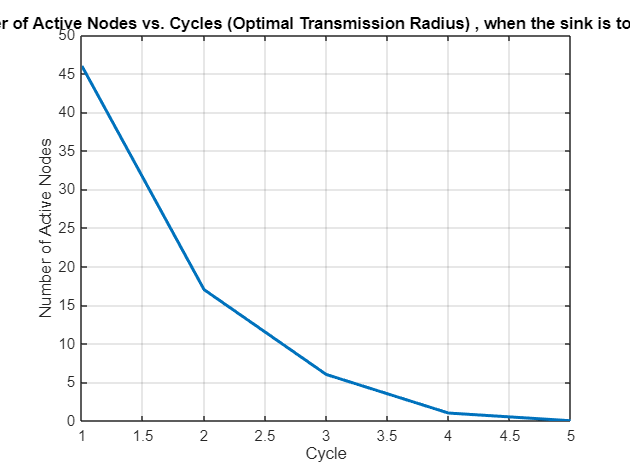

% Number of active nodes vs. cycles
figure(6);
plot(1:simulation_cycles_Optimal_Radious,alive_nodes_per_cycle_Optimal_Radious , 'LineWidth', 2);
title('Number of Active Nodes vs. Number of Cycles when the sink at farway of the network ');
xlabel('Cycle');
ylabel('Number of Active Nodes');
grid on;

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

%  Mark T1 on the plot
T1_Optimal_radious = find(alive_nodes_per_cycle_Optimal_Radious == N-1, 1); % First node dies
% Plot vertical lines to mark T1
hold on;
xline(T1_Optimal_radious, 'r--', 'LineWidth', 2, 'Label', 'T1 (First Node Dies)', 'LabelVerticalAlignment', 'bottom');
% Annotations for T1
plot(T1_Optimal_radious, alive_nodes_per_cycle_Optimal_Radious(T1_Optimal_radious), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
% Adjust axis limits for wider scale
xlim([0 max(T1_Optimal_radious*1.2, length(alive_nodes_per_cycle_Optimal_Radious))]); % Expands the x-axis by 20% more than T3
ylim([0 N+5]); % Adds a small buffer to the y-axis to give more space for labels
% Add labels and grid
title('Number of Active Nodes vs. Number of Cycles with T1 when the sink at the faraway of the network ');
xlabel('Number of Cycles');
ylabel('Number of Active Nodes');
grid on;
legend('Active Nodes', 'T1: First Node Dies');
hold off;

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

disp(['T1 (First node dies): ', num2str(T1_Optimal_radious), ' cycles']);

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part E_D_3 ****The remaning energy at the network in case of optimal transmission radious : **

figure(7);
T1_index = find(alive_nodes_per_cycle_Optimal_Radious == N - 1, 1);
bar_handles = bar(remaining_energy_per_cycle_Optimal_Radious(T1_index, :));
title('Remaining Energy of Nodes After T1 (First Node Dies)');
xlabel('Node Index');
ylabel('Remaining Energy (Joules)');
grid on;

% Customizing Bar Colors
alive_color = [0.6, 1, 0.6];
dead_color = [1, 1, 0.5];
hold on;
for i = 1:N
    if ismember(i, dead_nodes_at_T1_Optimal_Radious)
        bar(i, remaining_energy_per_cycle_Optimal_Radious(T1_index, i), 'FaceColor', dead_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    else
        bar(i, remaining_energy_per_cycle_Optimal_Radious(T1_index, i), 'FaceColor', alive_color, 'EdgeColor', 'k', 'LineWidth', 1.5);
    end
end
hold off;

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Observation for whole of Part E :**** When the sink is located at a distance roughly double the dimensions of the network, it becomes challenging for any node to transimit directly to the sink. This is because the energy required for such long-distance transmissions exceeds the available energy of the sensor nodes, making it infeasible for any node in the network to establish communication with the sink or be at least a relay node , due to their energies and distances, it was observed also that the model work when the sink where located at the edges the maximum distance to transimit with the given energies , and beyond that distance with the given energy it become difficult to transimit  .**

**---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Part F****  The following part is for the implementation of the new criteria of best relay node , when the sink is too far away , and show the figures for the number of active nodes versus number of cycles in case of optimal transimission  radious : **

close all;
clear all;
clc;

% Parameters
N = 100;                                             % Number of sensor nodes
A = 100;                                             % Network area size (100m x 100m)
x = randi([0, A], 1, N);                             % X-coordinates of sensor nodes
y = randi([0, A], 1, N);                             % Y-coordinates of sensor nodes
E_initial = 2;                                       % Initial energy for each node (2 Joules)
sink = [A/2, A/2+175];                               % Sink located at too much far distance from the network 
Eelec = 50e-9;                                       % Energy for running transmitter/receiver circuitry (J/bit)
Eagg= 50e-9;                                         % Energy for aggretation 
epsilon_fs = 10e-9;                                  % Free-space energy parameter (J/bit/m^2)
epsilon_mp = 0.0013e-9;                              % Multi-path energy parameter (J/bit/m^4)
d0 = sqrt(epsilon_fs / epsilon_mp);                  % Threshold distance
k = 4000;                                            % Number of bits transmitted per cycle
R = 30;                                              % Transmission range for direct communication
    

active_node_count = N;                             
alive_nodes_Optimal_Radious = N;
node_status_dead = false(1, N);  
node_status_dead_Optimal_Radious = false(1, N);
sensor_energy = E_initial * ones(1, N);             
sensor_energy_Optimal_Radious = E_initial * ones(1, N);
active_nodes_per_cycle = [];                       
alive_nodes_per_cycle_Optimal_Radious = [];
remaining_energy_per_cycle_Optimal_Radious = [];
simulation_cycles = 0;                              
simulation_cycles_Optimal_Radious = 0;
dead_nodes_at_T1_Optimal_Radious = [];


function [best_relay, E_updated] = enhanced_relay_selection(src_idx, sink, x, y, node_dead, E, d0, epsilon_fs, epsilon_mp)
    % Enhanced relay selection function with energy and distance optimization.
    % Inputs:
    % - src_idx: Index of the source node.
    % - sink: Coordinates of the sink [x_sink, y_sink].
    % - x, y: Coordinates of all nodes.
    % - node_dead: Boolean array indicating if a node is dead.
    % - E: Array of energy levels for all nodes.
    % - d0: Distance threshold for energy model switching.
    % - epsilon_fs: Free-space energy parameter.
    % - epsilon_mp: Multi-path energy parameter.
    % Output:
    % - best_relay: Index of the selected relay node.
    % - E_updated: Updated energy levels of all nodes.

    N = length(x);  % Total number of nodes
    best_relay = -1;  % Default to no relay
    E_updated = E;  % Copy of the energy levels
    max_energy = max(E);  % Maximum energy level among nodes
    relay_score = Inf;  % Initialize relay score to a high value

    for i = 1:N
        if ~node_dead(i) && i ~= src_idx
            % Calculate distances
            d_to_relay = sqrt((x(src_idx) - x(i))^2 + (y(src_idx) - y(i))^2);
            d_relay_to_sink = sqrt((x(i) - sink(1))^2 + (y(i) - sink(2))^2);

            % Energy consumption for the source-to-relay transmission
            if d_to_relay <= d0
                energy_src_to_relay = epsilon_fs * d_to_relay^2;
            else
                energy_src_to_relay = epsilon_mp * d_to_relay^4;
            end

            % Energy consumption for relay-to-sink transmission
            if d_relay_to_sink <= d0
                energy_relay_to_sink = epsilon_fs * d_relay_to_sink^2;
            else
                energy_relay_to_sink = epsilon_mp * d_relay_to_sink^4;
            end

            total_energy_cost = energy_src_to_relay + energy_relay_to_sink;

            % Check if the node can handle the required energy
            if E(i) >= total_energy_cost
                % Relay score: weighted sum of distance and energy (lower is better)
                score = 0.7 * (d_to_relay + d_relay_to_sink) / max(d0, max(max(x), max(y))) +  0.3 * (1 - E(i) / max_energy);
                if score < relay_score
                    relay_score = score;
                    best_relay = i;
                end
            end
        end
    end

    % Fallback: if no relay is found, use direct transmission to the sink
    if best_relay == -1
        distance_to_sink = sqrt((x(src_idx) - sink(1))^2 + (y(src_idx) - sink(2))^2);
        if distance_to_sink <= d0
            energy_cost = epsilon_fs * distance_to_sink^2;
        else
            energy_cost = epsilon_mp * distance_to_sink^4;
        end

        % Check if the source node has enough energy for direct transmission
        if E(src_idx) >= energy_cost
            best_relay = src_idx;  % Use the source node itself
        else
            error('No suitable relay or direct transmission possible.');
        end
    end

    % Update energy levels
    if best_relay ~= src_idx
        d_to_relay = sqrt((x(src_idx) - x(best_relay))^2 + (y(src_idx) - y(best_relay))^2);
        d_relay_to_sink = sqrt((x(best_relay) - sink(1))^2 + (y(best_relay) - sink(2))^2);

        % Update source node energy
        if d_to_relay <= d0
            E_updated(src_idx) = E_updated(src_idx) - (epsilon_fs * d_to_relay^2);
        else
            E_updated(src_idx) = E_updated(src_idx) - (epsilon_mp * d_to_relay^4);
        end

        % Update relay node energy
        if d_relay_to_sink <= d0
            E_updated(best_relay) = E_updated(best_relay) - (epsilon_fs * d_relay_to_sink^2);
        else
            E_updated(best_relay) = E_updated(best_relay) - (epsilon_mp * d_relay_to_sink^4);
        end
    end
end


% Calculate distances to the sink for all nodes
distances_to_sink = sqrt((x - sink(1)).^2 + (y - sink(2)).^2);
max_R = max(distances_to_sink);         % Maximum distance for direct communication

% Define range of transmission radii
R_values = 10:10:ceil(max_R);          % Transmission radii range
T1_values = NaN(1, length(R_values));  % Initialize T1 with NaN to handle empty cases

% Loop over different values of transmission radius
for radius_idx = 1:length(R_values)
    transmission_radius = R_values(radius_idx); % Current transmission radius
        % Simulation loop for current transmission radius
    while active_node_count > 0
        for node_idx = 1:N
            if ~node_status_dead(node_idx) && sensor_energy(node_idx) > 0 % Only process active nodes
                distance_to_sink = sqrt((x(node_idx) - sink(1))^2 + (y(node_idx) - sink(2))^2);
                if distance_to_sink <= transmission_radius
                    % Direct transmission
                    if distance_to_sink <= d0
                        energy_consumed = k * Eelec + k * epsilon_fs * distance_to_sink^2;
                    else
                        energy_consumed = k * Eelec + k * epsilon_mp * distance_to_sink^4;
                    end
                else
                    % Dual-hop transmission using enhanced relay selection
                    try
                        [best_relay_node, sensor_energy] = enhanced_relay_selection(node_idx, sink, x, y, node_status_dead, sensor_energy, d0, epsilon_fs, epsilon_mp);
                        distance_to_relay = sqrt((x(node_idx) - x(best_relay_node))^2 + (y(node_idx) - y(best_relay_node))^2);
                        distance_relay_to_sink = sqrt((x(best_relay_node) - sink(1))^2 + (y(best_relay_node) - sink(2))^2);

                        % Source energy consumption
                        if distance_to_relay <= d0
                            energy_consumed = k * Eelec + k * epsilon_fs * distance_to_relay^2;
                        else
                            energy_consumed = k * Eelec + k * epsilon_mp * distance_to_relay^4;
                        end

                        % Relay energy consumption
                        if distance_relay_to_sink <= d0
                            relay_energy_consumed = k * Eelec + k * epsilon_fs * distance_relay_to_sink^2 + k * Eagg;
                        else
                            relay_energy_consumed = k * Eelec + k * epsilon_mp * distance_relay_to_sink^4 + k * Eagg;
                        end

                        % Update relay energy
                        if sensor_energy(best_relay_node) > relay_energy_consumed
                            sensor_energy(best_relay_node) = sensor_energy(best_relay_node) - relay_energy_consumed;
                        else
                            node_status_dead(best_relay_node) = true;
                            active_node_count = active_node_count - 1;
                        end
                    catch
                        % Direct transmission fallback if no relay is available
                        if distance_to_sink <= d0
                            energy_consumed = k * Eelec + k * epsilon_fs * distance_to_sink^2;
                        else
                            energy_consumed = k * Eelec + k * epsilon_mp * distance_to_sink^4;
                        end
                    end
                end

                % Update source energy
                if sensor_energy(node_idx) > energy_consumed
                    sensor_energy(node_idx) = sensor_energy(node_idx) - energy_consumed;
                else
                    node_status_dead(node_idx) = true;
                    active_node_count = active_node_count - 1;
                end
            end
        end

        % Store active nodes per cycle
        active_nodes_per_cycle = [active_nodes_per_cycle, active_node_count];
        simulation_cycles = simulation_cycles + 1;
    end

    % Store network lifetime for current transmission radius
    if any(active_nodes_per_cycle == N - 1)
        T1_values(radius_idx) = find(active_nodes_per_cycle == N - 1, 1);
    else
        T1_values(radius_idx) = Inf; % Assign Inf if no nodes die
    end
end

% Determine the optimal transmission radius
[~, optimal_transmission_radius_idx] = max(T1_values(~isinf(T1_values))); % Exclude Inf values
optimal_transmission_radius = R_values(optimal_transmission_radius_idx);

% Optimal radius simulation loop
while alive_nodes_Optimal_Radious > 0
    for i = 1:N
        if ~node_status_dead_Optimal_Radious(i) && sensor_energy_Optimal_Radious(i) > 0
            distance_to_sink = sqrt((x(i) - sink(1))^2 + (y(i) - sink(2))^2);
            if distance_to_sink <= optimal_transmission_radius
                % Direct Transmission
                if distance_to_sink <= d0
                    energy_consumed = k * Eelec + k * epsilon_fs * distance_to_sink^2;
                else
                    energy_consumed = k * Eelec + k * epsilon_mp * distance_to_sink^4;
                end
            else
                % Dual-Hop Transmission
                try
                    [best_relay, sensor_energy_Optimal_Radious] = enhanced_relay_selection(i, sink, x, y, node_status_dead_Optimal_Radious, sensor_energy_Optimal_Radious, d0, epsilon_fs, epsilon_mp);
                    distance_to_relay = sqrt((x(i) - x(best_relay))^2 + (y(i) - y(best_relay))^2);
                    distance_relay_to_sink = sqrt((x(best_relay) - sink(1))^2 + (y(best_relay) - sink(2))^2);

                    % Source Node Energy Consumption
                    if distance_to_relay <= d0
                        energy_consumed = k * Eelec + k * epsilon_fs * distance_to_relay^2;
                    else
                        energy_consumed = k * Eelec + k * epsilon_mp * distance_to_relay^4;
                    end

                    % Relay Node Energy Consumption
                    if distance_relay_to_sink <= d0
                        relay_energy_consumed = k * Eelec + k * epsilon_fs * distance_relay_to_sink^2 + k * Eagg;
                    else
                        relay_energy_consumed = k * Eelec + k * epsilon_mp * distance_relay_to_sink^4 + k * Eagg;
                    end

                    if sensor_energy_Optimal_Radious(best_relay) > relay_energy_consumed
                        sensor_energy_Optimal_Radious(best_relay) = sensor_energy_Optimal_Radious(best_relay) - relay_energy_consumed;
                    else
                        node_status_dead_Optimal_Radious(best_relay) = true;
                        alive_nodes_Optimal_Radious = alive_nodes_Optimal_Radious - 1;
                        if isempty(dead_nodes_at_T1_Optimal_Radious) && alive_nodes_Optimal_Radious == N - 1
                            dead_nodes_at_T1_Optimal_Radious = find(node_status_dead_Optimal_Radious);
                        end
                    end
                catch
                    % Fallback to direct transmission
                    if distance_to_sink <= d0
                        energy_consumed = k * Eelec + k * epsilon_fs * distance_to_sink^2;
                    else
                        energy_consumed = k * Eelec + k * epsilon_mp * distance_to_sink^4;
                    end
                end
            end

            % Update source energy
            if sensor_energy_Optimal_Radious(i) > energy_consumed
                sensor_energy_Optimal_Radious(i) = sensor_energy_Optimal_Radious(i) - energy_consumed;
            else
                node_status_dead_Optimal_Radious(i) = true;
                alive_nodes_Optimal_Radious = alive_nodes_Optimal_Radious - 1;
                if isempty(dead_nodes_at_T1_Optimal_Radious) && alive_nodes_Optimal_Radious == N - 1
                    dead_nodes_at_T1_Optimal_Radious = find(node_status_dead_Optimal_Radious);
                end
            end
        end
    end

    % Store Alive Nodes and Energy Per Cycle
    alive_nodes_per_cycle_Optimal_Radious = [alive_nodes_per_cycle_Optimal_Radious, alive_nodes_Optimal_Radious];
    remaining_energy_per_cycle_Optimal_Radious = [remaining_energy_per_cycle_Optimal_Radious; sensor_energy_Optimal_Radious];
    simulation_cycles_Optimal_Radious = simulation_cycles_Optimal_Radious + 1;
end

**Part F_1  ****Number of active nodes versus number of cycles in case of optimal radious , when the sink is too much far away from the network **

% Plot results
figure(10);
plot(1:simulation_cycles_Optimal_Radious, alive_nodes_per_cycle_Optimal_Radious, 'LineWidth', 2);
title('Number of Active Nodes vs. Cycles (Optimal Transmission Radius) , when the sink is to far away ');
xlabel('Cycle');
ylabel('Number of Active Nodes');
grid on;

**                                                                Figure [10]**

**                    the figure shows number of active nodes versus number of cycles , **

**                              till the death of last node , when the sink is too much**

**                                     far way from the network , and in case of **

**                                                           optimal radious . **

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Conclusion : ****In this part of the project, it was observed how the model behaves when the distance between the sensors and the sink is less than the transmission radius. Specifically, it was analyzed whether using direct transmission or dual-hop transmission consumes less energy compared to other techniques. Additionally, when the sink is positioned far away, even at the edges of the network, it was noted how the proposed technique with the best relay function fails to work effectively. In such cases, the energy of the nodes becomes insufficient for transmission, rendering them ineffective.**

**-----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**                                                                                                                                                                                                                                                                                               Done by. Nada tayel Khafagy  **

**                                                                                                                                                                                                                                                                         under the supervision of DR. Smay Soliman && Ta. Heba selim **

                                                                                                                                                                                                                                                                          **  in Wireless Sensor network and IOT || CIE 510 || Fall 2024 **

**                                                                                                                                                                                                                                                                                                            at UST || Zewail City**